## Tiny Test

to test if the sensing matix A is built correctly

% Tiny example to verify DD domain channel estimation framework
%% Parameters (keep small for verification)
M = 4;  % Number of delay bins (time samples)
N = 4;  % Number of Doppler bins (subcarriers)

%% Step 1: Generate sparse channel in DD domain
% Create a sparse channel with few non-zero taps
h_DD = zeros(M, N);
% Add a few channel taps (sparse)
h_DD(2, 1) = 0.5 + 0.3i;   % (delay=1, doppler=0)
h_DD(1, 2) = 0.8 - 0.2i;   % (delay=0, doppler=1)
h_DD(2, 3) = 0.3 + 0.4i;   % (delay=1, doppler=2)

h_DD_vec = h_DD(:);  % Vectorize for later use

fprintf('Number of non-zero channel taps: %d out of %d\n', nnz(h_DD), M*N);

Number of non-zero channel taps: 3 out of 16



%% Step 2: Generate transmitted signal in DD domain
X_DD = (randn(M, N) + 1i*randn(M, N)) / sqrt(2);

%% Step 3: Convert to TF domain using SFFT (Symplectic FFT)
% DD to TF: FFT along delay (dim 1), IFFT along Doppler (dim 2)
H_TF = fft(ifft(h_DD, [], 2), [], 1);
X_TF = fft(ifft(X_DD, [], 2), [], 1);

%% Step 4: Generate received signal in TF domain (element-wise multiplication)
Y_TF = H_TF .* X_TF;

%% Step 5: Convert received signal back to DD domain
% TF to DD: IFFT along time (dim 1), FFT along frequency (dim 2)
y_DD_correct = ifft(fft(Y_TF, [], 2), [], 1);
y_DD_correct_vec = y_DD_correct(:);  % Vectorize

%% Step 6: Construct sensing matrix A
% A represents the operation: y_DD = A * h_DD
% where the transformation involves SFFT operations

A_tiny = zeros(M*N, M*N);
for k = 1:M*N
    % Create a unit vector
    e_k = zeros(M*N, 1);
    e_k(k) = 1;
    
    % Reshape to 2D (M x N)
    H_k = reshape(e_k, M, N);
    
    % Apply the operation:
    % 1. Convert X_DD and H_k to TF domain
    X_TF_temp = fft(ifft(X_DD, [], 2), [], 1);
    H_TF_k = fft(ifft(H_k, [], 2), [], 1);
    
    % 2. Element-wise multiplication in TF domain
    Y_TF_k = X_TF_temp .* H_TF_k;
    
    % 3. Convert back to DD domain
    Y_k = ifft(fft(Y_TF_k, [], 2), [], 1);
    
    % Store as column in A
    A_tiny(:, k) = Y_k(:);
end

%% Step 7: Verify: compute y_check using matrix A
y_DD_check = A_tiny * h_DD_vec;

%% Step 8: Compare results
error = norm(y_DD_correct_vec - y_DD_check) / norm(y_DD_correct_vec);
fprintf('Relative error:       %.2e\n', error);

Relative error:       1.30e-16


## End of tiny test

function A = construct_sensing_matrix_DD(X_DD)
% CONSTRUCT_SENSING_MATRIX_DD Constructs the sensing matrix A for DD domain
% channel estimation in OTFS systems
%
% Input:
%   X_DD - Transmitted signal in Delay-Doppler domain (M x N matrix)
%
% Output:
%   A - Sensing matrix (M*N x M*N) such that y_DD = A * h_DD
%       where h_DD is the vectorized sparse channel in DD domain
%
% The matrix A encodes the operation:
%   y_DD = IFFT_time(FFT_freq(Y_TF))
%   where Y_TF = X_TF .* H_TF (element-wise multiplication in TF domain)

    % Get dimensions
    [M, N] = size(X_DD);  % M: delay bins, N: Doppler bins
    
    % Pre-compute X_TF (DD to TF transformation of transmitted signal)
    % DD to TF: FFT along delay (dim 1), IFFT along Doppler (dim 2)
    X_TF = fft(ifft(X_DD, [], 2), [], 1);
    
    % Initialize sensing matrix
    A = zeros(M*N, M*N);
    
    % Construct matrix A column by column
    for k = 1:M*N
        % Create a unit impulse at position k
        e_k = zeros(M*N, 1);
        e_k(k) = 1;
        
        % Reshape to 2D (M x N)
        H_k = reshape(e_k, M, N);
        
        % Transform H_k to TF domain
        % DD to TF: FFT along delay (dim 1), IFFT along Doppler (dim 2)
        H_TF_k = fft(ifft(H_k, [], 2), [], 1);
        
        % Element-wise multiplication in TF domain
        Y_TF_k = X_TF .* H_TF_k;
        
        % Convert back to DD domain
        % TF to DD: IFFT along time (dim 1), FFT along frequency (dim 2)
        Y_k = ifft(fft(Y_TF_k, [], 2), [], 1);
        
        % Store as column in A
        A(:, k) = Y_k(:);
    end
end

txgrid, rxGrid, H_perfect_n are got from the Gen_Chan_DD,mlx after line 768

txGrid_DD = ifft(fft(txGrid, [], 2), [], 1); % rank(txGrid) =3
rxGrid_DD = ifft(fft(rxGrid, [], 2), [], 1); % rxGrid received by waveform → channel filter

rxGrid_straightTF = txGrid .* H_perfect_n;    % straight compute Y_TF = H_TF . X_TF, not convert to time-domain waveform
                                               % NOTE: the values at the pilot elements are very different with rxGrid
rxGrid_straightTF_toDD = ifft(fft(rxGrid_straightTF, [], 2), [], 1);


% idx = 60;
% H_li_DD = tf2dd(H_li(:,:,idx).');
% H_prac_DD = tf2dd(H_prac(:,:,idx).');
% H_ls_DD = tf2dd(H_ls(:,:,idx).');
% 
H_perfect_n_DD = ifft(fft(H_perfect_n, [], 2), [], 1);
H_perfect_n_before_DD = ifft(fft(H_perfect_n_before, [], 2), [], 1);

figure; imagesc(real(H_perfect_n)); colorbar

y_DD_vec = rxGrid_DD(:);
% y_all = [real(y); imag(y)];
% % A_all = [real(A); imag(A)];
% 
% A_real = [real(A)  -imag(A);
%           imag(A)   real(A)];
% y_real = [real(y); imag(y)];

## Test A 

Test A by checking if rxGrid_DD = A * h_perfect_DD   (y=Ah)

Asumming known h, known A, 

y_correct = vectorize( H. X )

    convert into DD domain

y_check_DD = A * h_DD

    check if y_check_DD = y_correct_DD

h_perfect_complex_vec = H_perfect_n_DD(:);
% h_perfect_real = [ real(h_perfect_complex); imag(h_perfect_complex) ];

A_test = construct_sensing_matrix_DD(txGrid_DD); % rank(txGrid_DD)=3
y_check = A_test * h_perfect_complex_vec;

y_check_straight_TF_toDD = A_test * h_perfect_complex_vec(:);

a_test = (y_check- y_DD_vec);
error = norm(y_check - y_DD_vec) / norm(y_DD_vec)

error = 0.9997


error_straight = norm(y_check_straight_TF_toDD - rxGrid_straightTF_toDD(:)) / norm(rxGrid_straightTF_toDD(:))

error_straight = 9.0176e-16

% rank(rxGrid_straightTF_toDD) = 3
% rank(A_test) = 132  --> not full rank

→ good sensing matrix A

## Not used Compressed Sensing

#### Using channel filter, txWaveform

H_LS_TF = H_equalized_n;
H_LI_TF = zeros(size(H_linear_n));
H_LI_TF(:,3) = H_linear_n(:,3);
H_LI_TF(:,8) = H_linear_n(:,8);
H_LI_TF(:,12) = H_linear_n(:,12);

H_LS_DD = ifft(fft(H_LS_TF, [], 2), [], 1);
H_LI_DD = ifft(fft(H_LI_TF, [], 2), [], 1);

function [H_DD_sparse, H_TF_full, support] = extract_sparse_DD(H_DD, K_sparse)
    % Extract K largest magnitude elements from DD domain channel
    %
    % Inputs:
    %   H_DD - [M x N] channel in DD domain (e.g., H_LS_DD or H_LI_DD)
    %   K_sparse - number of dominant taps to keep
    %
    % Outputs:
    %   H_DD_sparse - [M x N] sparse DD channel (only K non-zeros)
    %   H_TF_full - [M x N] full TF channel (all positions filled)
    %   support - linear indices of the K selected taps
    
    [M, N] = size(H_DD);
    
    %% Step 1: Find K largest magnitude elements
    
    % Flatten to vector
    h_vec = H_DD(:);
    
    % Get magnitudes
    magnitudes = abs(h_vec);
    
    % Sort by magnitude (descending)
    [sorted_mags, sorted_idx] = sort(magnitudes, 'descend');
    
    % Keep top K indices
    support = sorted_idx(1:K_sparse);
    
    fprintf('Extracted %d largest taps:\n', K_sparse);
    fprintf('  Largest:  %.4e\n', sorted_mags(1));
    fprintf('  Smallest: %.4e\n', sorted_mags(K_sparse));
    fprintf('  Ratio:    %.2f\n', sorted_mags(1) / sorted_mags(K_sparse));
    
    %% Step 2: Create sparse DD channel
    
    H_DD_sparse = zeros(M, N);
    h_sparse_vec = zeros(M*N, 1);
    h_sparse_vec(support) = h_vec(support);  % Keep only selected elements
    H_DD_sparse = reshape(h_sparse_vec, [M, N]);
    
    fprintf('  Non-zeros in sparse DD: %d\n', nnz(H_DD_sparse));
    
    %% Step 3: Transform to TF domain (recover full channel)
    
    % DD → TF:  FFT in frequency, IFFT in time
    H_TF_full = fft(ifft(H_DD_sparse, [], 2), [], 1);
    
    fprintf('  Full TF channel: %d x %d (all positions estimated)\n', M, N);
    
end

K_sparse_ = 10;  % Number of dominant taps to keep

%% Process LS estimate
[H_LS_DD_sparse, H_LS_TF_full, support_LS] = extract_sparse_DD(H_LS_DD, K_sparse_);

Extracted 10 largest taps:
  Largest:  7.4701e-09
  Smallest: 5.6014e-09
  Ratio:    1.33
  Non-zeros in sparse DD: 10
  Full TF channel: 132 x 14 (all positions estimated)



%% Process LI estimate
[H_LI_DD_sparse, H_LI_TF_full, support_LI] = extract_sparse_DD(H_LI_DD, K_sparse_);

Extracted 10 largest taps:
  Largest:  2.2339e-08
  Smallest: 6.8605e-09
  Ratio:    3.26
  Non-zeros in sparse DD: 10
  Full TF channel: 132 x 14 (all positions estimated)


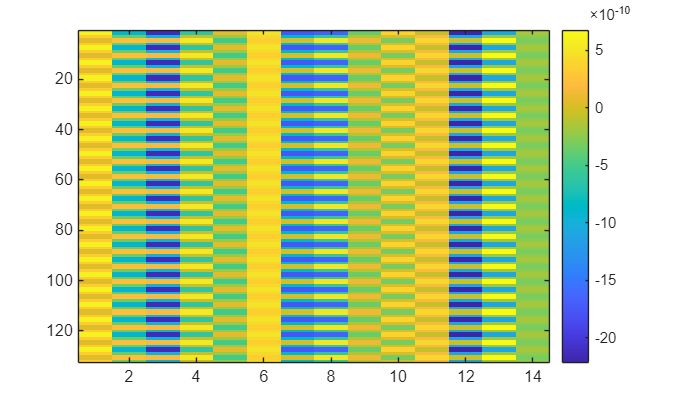

figure
imagesc(real(H_LS_TF_full));
colorbar

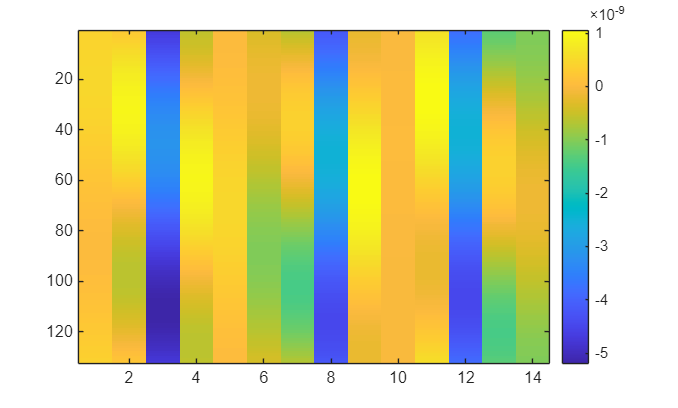


figure
imagesc(real(H_LI_TF_full));
colorbar

→ Not good results

#### Using straight TF grid Y = X .* H

rxGrid_straightTF = txGrid .* H_perfect_n

H_LS_noNoise = H_perfect_n .* (txGrid ~= 0);
H_LS_noNoise_DD = ifft(fft(H_LS_noNoise, [], 2), [], 1);

[~, H_LS_noNoise_TF_full, support_LS] = extract_sparse_DD(H_LS_noNoise_DD, K_sparse_);

Extracted 10 largest taps:
  Largest:  6.8500e-09
  Smallest: 5.1510e-09
  Ratio:    1.33
  Non-zeros in sparse DD: 10
  Full TF channel: 132 x 14 (all positions estimated)


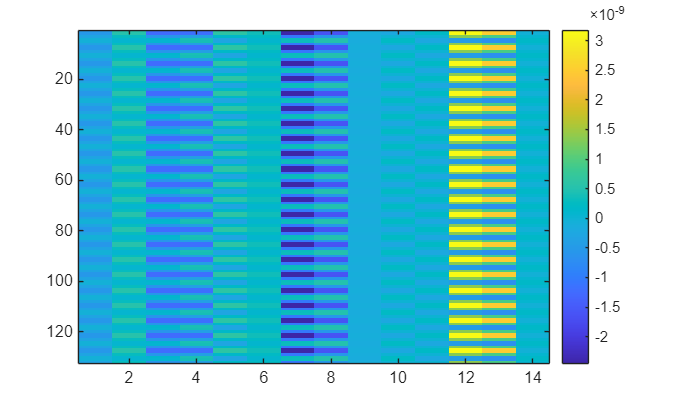

figure
imagesc(real(H_LS_noNoise_TF_full));
colorbar

→ Even with no noise, it is still not good

For LI 

rxGrid_straightTF = txGrid .* H_perfect_n - no Noise considered

function H_LI = linear_interpolate_2D(H_LS_noNoise, pilot_mask)
    % 2D Linear interpolation of channel from pilot positions to all positions
    %
    % Inputs:
    %   H_LS_noNoise - [K x N] channel with values only at pilot positions
    %   pilot_mask - [K x N] logical array (true where pilots exist)
    %
    % Output:
    %   H_LI - [K x N] linearly interpolated channel (all positions)
    
    [K, N] = size(H_LS_noNoise);
    
    % Find row and column coordinates of pilots
    [rows, cols] = find(pilot_mask);
    pilot_values = H_LS_noNoise(pilot_mask);
    
    % Get unique pilot symbols (columns)
    pilot_cols = unique(cols);
    
    %% Check how many pilot symbols we have
    if isscalar(pilot_cols)
        % Only 1 symbol containing pilots -> duplicate
        col_idx = pilot_cols(1);
        
        % Interpolate along rows (subcarriers) for the pilot column
        query_rows = (1:K)';
        H_LI = zeros(K, N);
        H_LI(:, col_idx) = interp1(rows, pilot_values, query_rows, 'linear', 'extrap');
        
        % Duplicate to all other columns
        for n = 1:N
            if n ~= col_idx
                H_LI(:, n) = H_LI(:, col_idx);
            end
        end
        
    else
        % Multiple pilot symbols -> 2D scattered interpolation
        
        % Create query grid (all positions)
        [col_grid, row_grid] = meshgrid(1:N, 1:K);
        
        % Scattered interpolant (column, row, value)
        F = scatteredInterpolant(cols, rows, pilot_values, 'linear', 'nearest');
        
        % Interpolate to all positions
        H_LI = F(col_grid, row_grid);
    end
end

H_LI_noNoise = linear_interpolate_2D(H_LS_noNoise, H_LS_noNoise~=0);
nmse = norm(H_perfect_n - H_LI_noNoise)^2 / norm(H_perfect_n)^2

nmse = 0.1143

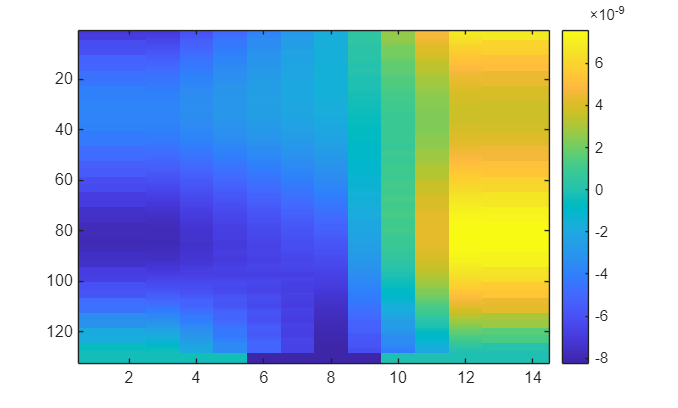

figure
imagesc(real(H_LI_noNoise));
colorbar

→ Even with perfect LS (no noise), LI still not good at the extrapolated elements

H_LI_noNoise_DD = ifft(fft(H_LI_noNoise, [], 2), [], 1);
[~, H_LI_noNoise_TF_full, support_LS] = extract_sparse_DD(H_LI_noNoise_DD, 50); %  K_sparse_

Extracted 50 largest taps:
  Largest:  7.0982e-08
  Smallest: 2.2588e-09
  Ratio:    31.42
  Non-zeros in sparse DD: 50
  Full TF channel: 132 x 14 (all positions estimated)


nmse = norm(H_perfect_n - H_LI_noNoise_TF_full)^2 / norm(H_perfect_n)^2

nmse = 0.1129

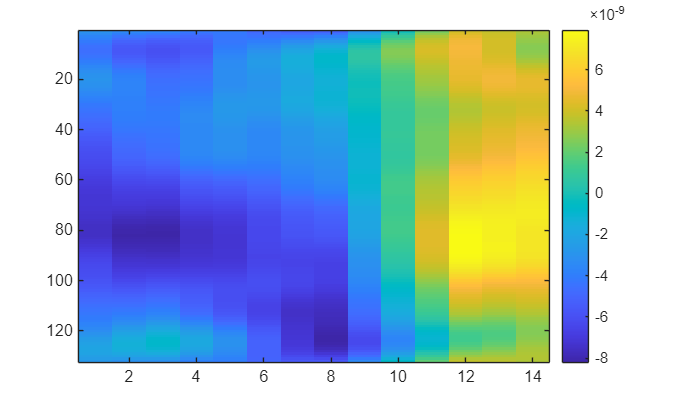

figure
imagesc(real(H_LI_noNoise_TF_full));
colorbar

## Channel estimation problem with Compressed Sensing

Known A, known y, estimate h

y_DD = A* h_DD

y_DD is the expression in DD domain of Y (received TF grid)

## Lasso

y = rxGrid_straightTF_toDD(:);
A_real = [real(A_test)  -imag(A_test);
          imag(A_test)   real(A_test)];
y_real = [real(y); imag(y)];

[h_hat_real, info] = lasso(A_real, y_real);
% [h_hat_cv, info] = lasso(A_real, y_real, 'CV', 5, 'Intercept', true, 'Standardize', true);

[~, idx] = min(info.MSE);

idx = 20;
h_hat_vec = h_hat_real(:, idx);  % length = 2 * 1848

% Recover complex h
h_complex = h_hat_vec(1:end/2) + 1j * h_hat_vec(end/2 + 1:end);

Hest_DD = reshape(h_complex, 132, 14);
Hest_DD_TF = fft(ifft(Hest_DD, [], 2), [], 1);

error_nmse = norm(H_perfect_n - Hest_DD_TF)^2 / norm(H_perfect_n)^2

figure
imagesc(real(Hest_DD_TF));
colorbar

## OMP (Starting Point) 

#### Complex OMP 

function [x, support] = OMP_complex(A, y, K_sparse, tol)
    % OMP for complex-valued matrices and signals
    % Inputs:
    %   A: [M x N] complex sensing matrix
    %   y: [M x 1] complex measurements
    %   K_sparse: sparsity level (number of non-zero elements)
    %   tol: (optional) residual tolerance for early stopping
    %
    % Outputs:
    %   x: [N x 1] estimated sparse signal
    %   support: indices of non-zero elements
    
    if nargin < 4
        tol = 1e-6;
    end
    
    [M, N] = size(A);
    x = zeros(N, 1);
    residual = y;
    support = [];
    
    for iter = 1:K_sparse
        % Compute correlations (complex inner product)
        correlations = abs(A' * residual);  % abs() for magnitude
        
        % Find maximum correlation
        [~, idx] = max(correlations);
        
        % Add to support
        support = [support; idx];
        
        % Least squares on current support (complex LS)
        A_support = A(:, support);
        x_support = A_support \ y;  % MATLAB handles complex LS automatically
        
        % Update residual
        residual = y - A_support * x_support;
        
        % Check stopping criterion
        if norm(residual) < tol
            break;
        end
    end
    
    % Assign solution
    x(support) = x_support;
end

K_sparse = 5;

% Complex sensing matrix
A_omp = A_test;
% Measurements
y = rxGrid_straightTF_toDD(:);

% Run OMP
[h_est_omp, support_est_omp] = OMP_complex(A_omp, y, K_sparse);

% Evaluate
Hest_DD_omp = reshape(h_est_omp, 132, 14);
Hest_DD_TF_omp = fft(ifft(Hest_DD_omp, [], 2), [], 1);
error_nmse = norm(H_perfect_n - Hest_DD_TF_omp)^2 / norm(H_perfect_n)^2

error_nmse = 0.2038

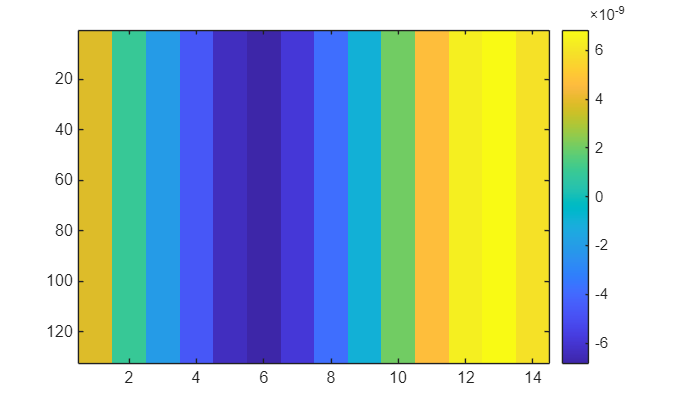

figure
imagesc(real(Hest_DD_TF_omp));
colorbar

#### Real-Imaginary Separation (Sometimes More Stable)

function [x, support] = OMP_real_imag(A, y, K_sparse, tol)
    % OMP with real-imaginary separation
    % Converts complex problem to real-valued problem
    
    if nargin < 4
        tol = 1e-6;
    end
    
    [M, N] = size(A);
    
    % Convert to real-valued problem
    % [real(y)]   [real(A)  -imag(A)] [real(x)]
    % [imag(y)] = [imag(A)   real(A)] [imag(x)]
    
    A_real = [real(A), -imag(A);
              imag(A),  real(A)];
    y_real = [real(y); imag(y)];
    
    % Run OMP on real system (2M x 2N)
    [x_real, ~] = OMP_real_core(A_real, y_real, K_sparse, tol, N);
    
    % Convert back to complex
    x = x_real(1:N) + 1i*x_real(N+1:2*N);
    
    % Find support
    support = find(abs(x) > 1e-10);
end

function [x, support] = OMP_real_core(A, y, K_sparse, tol, N_original)
    % Core OMP for real-valued problem with paired selection
    
    [M, N] = size(A);
    x = zeros(N, 1);
    residual = y;
    support = [];
    
    for iter = 1:K_sparse
        % Compute correlations
        correlations = A' * residual;
        
        % For complex problem, pair real/imag parts
        if N == 2*N_original
            % Combine correlations for real and imaginary parts
            corr_combined = zeros(N_original, 1);
            for i = 1:N_original
                corr_combined(i) = norm([correlations(i); correlations(i + N_original)]);
            end
            [~, idx] = max(corr_combined);
            
            % Add both real and imaginary indices
            new_support = [idx; idx + N_original];
        else
            % Standard real OMP
            [~, idx] = max(abs(correlations));
            new_support = idx;
        end
        
        % Add to support
        support = [support; new_support];
        support = unique(support);  % Remove duplicates
        
        % Least squares on current support
        A_support = A(:, support);
        x_support = A_support \ y;
        
        % Update residual
        residual = y - A_support * x_support;
        
        % Check stopping criterion
        if norm(residual) < tol
            break;
        end
    end
    
    % Assign solution
    x(support) = x_support;
end

% Run OMP with real-imag separation
[h_est_omp2, support_est_omp2] = OMP_real_imag(A_omp, y, K_sparse);

% Evaluate
Hest_DD_omp2 = reshape(h_est_omp2, 132, 14);
Hest_DD_TF_omp2 = fft(ifft(Hest_DD_omp2, [], 2), [], 1);
error_nmse = norm(H_perfect_n - Hest_DD_TF_omp2)^2 / norm(H_perfect_n)^2

error_nmse = 0.2038


figure
imagesc(real(Hest_DD_TF_omp2));
colorbar

The nmse result is the same as the complex one 

####  Optimized Complex OMP with CoSaMP Variant

function [x, support] = OMP_complex_optimized(A, y, K_sparse)
    % Optimized OMP with better numerical stability
    
    [M, N] = size(A);
    
    % Normalize columns of A for numerical stability
    A_norms = sqrt(sum(abs(A).^2, 1));
    A_normalized = A ./ A_norms;
    
    % Initialize
    x = zeros(N, 1);
    residual = y;
    support = [];
    
    % Precompute A' for efficiency
    AH = A_normalized';
    
    for iter = 1:K_sparse
        % Compute correlations using Hermitian transpose
        correlations = abs(AH * residual);
        
        % Find maximum correlation
        [~, idx] = max(correlations);
        
        % Avoid selecting same index twice
        if ismember(idx, support)
            correlations(idx) = 0;
            [~, idx] = max(correlations);
        end
        
        % Add to support
        support = [support; idx];
        
        % Least squares with QR decomposition (more stable)
        A_support = A_normalized(:, support);
        [Q, R] = qr(A_support, 0);
        x_support = R \ (Q' * y);
        
        % Update residual
        residual = y - A_support * x_support;
        
        % Early stopping
        if norm(residual) / norm(y) < 1e-6
            break;
        end
    end
    
    % Rescale solution
    x(support) = x_support ./ A_norms(support).';
end

[h_est_omp3, support_est_omp3] = OMP_complex_optimized(A_omp, y, K_sparse);

% Evaluate
Hest_DD_omp3 = reshape(h_est_omp3, 132, 14);
Hest_DD_TF_omp3 = fft(ifft(Hest_DD_omp2, [], 2), [], 1);
error_nmse = norm(H_perfect_n - Hest_DD_TF_omp3)^2 / norm(H_perfect_n)^2

error_nmse = 0.2038

figure
imagesc(real(Hest_DD_TF_omp3));
colorbar

Still the same nmse

## AMP (Best Performance) 

function [x, history] = AMP_complex(A, y, K_sparse, options)
    % AMP for complex compressed sensing
    %
    % Inputs:
    %   A         - [M x N] complex sensing matrix
    %   y         - [M x 1] complex measurements
    %   K_sparse  - expected sparsity level
    %   options   - (optional) struct with fields:
    %               .max_iter: maximum iterations (default: 100)
    %               .tol: convergence tolerance (default: 1e-6)
    %               .verbose: display progress (default: true)
    %               .sigma_noise: noise std (default: auto-estimate)
    %
    % Outputs:
    %   x         - [N x 1] estimated sparse signal
    %   history   - struct with convergence information
    
    % Parse options
    if nargin < 4
        options = struct();
    end
    max_iter = getfield_default(options, 'max_iter', 100);
    tol = getfield_default(options, 'tol', 1e-6);
    verbose = getfield_default(options, 'verbose', true);
    sigma_noise = getfield_default(options, 'sigma_noise', []);
    
    [M, N] = size(A);
    delta = M / N;
    
    % Initialize
    x = zeros(N, 1);
    z = y;
    
    % Auto-estimate noise if not provided
    if isempty(sigma_noise)
        sigma_noise = median(abs(y)) / 0.6745;  % MAD estimator
    end
    sigma_sq = sigma_noise^2;
    
    % History
    history.residual = zeros(max_iter, 1);
    history.sparsity = zeros(max_iter, 1);
    history.threshold = zeros(max_iter, 1);
    
    if verbose
        fprintf('AMP: M=%d, N=%d, ratio=%.3f, sigma=%.2e\n', ...
            M, N, delta, sigma_noise);
    end
    
    for t = 1:max_iter
        x_old = x;
        
        % Effective signal
        s = x + A' * z;
        
        % Adaptive threshold
        k_current = nnz(abs(x) > 1e-10);
        k_eff = max(k_current, K_sparse);
        tau = sqrt(2 * sigma_sq * log(N / max(k_eff, 1)));
        
        % Complex soft thresholding
        x = soft_threshold_complex(s, tau);
        
        % Onsager correction
        div_eta = nnz(abs(x) > 1e-10) / M;
        
        % Update residual
        z = y - A * x + z * div_eta;
        
        % Update noise estimate (optional, for adaptive version)
        sigma_sq = 0.9 * sigma_sq + 0.1 * (norm(z)^2 / M);
        
        % Store history
        history.residual(t) = norm(y - A * x);
        history.sparsity(t) = nnz(abs(x) > 1e-10);
        history.threshold(t) = tau;
        
        % Check convergence
        rel_change = norm(x - x_old) / (norm(x) + eps);
        
        if verbose && (mod(t, 20) == 0 || t == max_iter)
            fprintf('Iter %3d: k=%3d, ||r||=%.2e, tau=%.2e, change=%.2e\n', ...
                t, history.sparsity(t), history.residual(t), tau, rel_change);
        end
        
        if rel_change < tol && t > 10
            if verbose
                fprintf('Converged at iteration %d\n', t);
            end
            break;
        end
    end
    
    % Trim history
    history.residual = history.residual(1:t);
    history.sparsity = history.sparsity(1:t);
    history.threshold = history.threshold(1:t);
    history.iterations = t;
end

function x = soft_threshold_complex(s, tau)
    % Complex soft thresholding
    magnitude = abs(s);
    x = s .* max(0, 1 - tau ./ (magnitude + eps));
end

function val = getfield_default(s, field, default)
    if isfield(s, field)
        val = s.(field);
    else
        val = default;
    end
end

[h_est_amp, history] = AMP_complex(A_test, y, K_sparse);

AMP: M=1848, N=1848, ratio=1.000, sigma=8.50e-10
Iter  20: k= 28, ||r||=1.29e-08, tau=1.33e-09, change=2.35e-02
Iter  40: k= 25, ||r||=1.03e-08, tau=8.54e-10, change=8.78e-03
Iter  60: k= 32, ||r||=8.85e-09, tau=6.56e-10, change=6.07e-03
Iter  80: k= 27, ||r||=8.17e-09, tau=5.87e-10, change=4.02e-03
Iter 100: k= 21, ||r||=7.94e-09, tau=5.69e-10, change=2.55e-03



Hest_DD_amp = reshape(h_est_amp, 132, 14);
Hest_DD_TF_amp = fft(ifft(Hest_DD_amp, [], 2), [], 1);
error_nmse = norm(H_perfect_n - Hest_DD_TF_amp)^2 / norm(H_perfect_n)^2

error_nmse = 0.7399

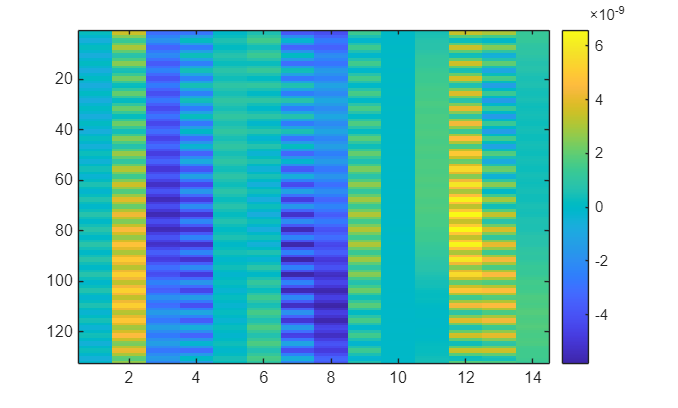


figure
imagesc(real(Hest_DD_TF_amp));
colorbar

#### Improved AMP 

function [x, history] = AMP_improved(A, y, K_sparse, options)
    % Improved AMP with multiple enhancements
    %
    % Enhancements:
    %   - Column normalization for stability
    %   - Adaptive threshold schedule
    %   - Debiasing via least squares refinement
    %   - Better noise estimation
    %   - Hard thresholding refinement
    %
    % Same input/output as AMP_complex
    
    % Parse options
    if nargin < 4
        options = struct();
    end
    max_iter = getfield_default(options, 'max_iter', 150);
    tol = getfield_default(options, 'tol', 1e-6);
    verbose = getfield_default(options, 'verbose', true);
    debias = getfield_default(options, 'debias', true);
    
    [M, N] = size(A);
    
    % Normalize columns for numerical stability
    A_norms = sqrt(sum(abs(A).^2, 1));
    A_normalized = A ./ (A_norms + eps);
    
    % Initialize
    x = zeros(N, 1);
    z = y;
    
    % Initial noise estimate
    x_init = A_normalized' * y;
    residual_init = y - A_normalized * x_init;
    sigma_sq = norm(residual_init)^2 / M;
    
    % History
    history.residual = zeros(max_iter, 1);
    history.sparsity = zeros(max_iter, 1);
    history.threshold = zeros(max_iter, 1);
    history.sigma = zeros(max_iter, 1);
    
    if verbose
        fprintf('Improved AMP: M=%d, N=%d, ratio=%.3f\n', M, N, M/N);
    end
    
    % Main iteration
    for t = 1:max_iter
        x_old = x;
        
        % Signal estimate
        r = x + A_normalized' * z;
        
        % Adaptive threshold with schedule
        k_current = max(nnz(abs(x) > 1e-10), 1);
        
        if t <= 15
            % Aggressive early on
            lambda = sqrt(2 * sigma_sq * log(N)) * (1 + 0.5 * exp(-t/5));
        else
            % Conservative later
            lambda = sqrt(2 * sigma_sq * log(N / k_current));
        end
        
        % Soft thresholding
        x = soft_threshold_complex(r, lambda);
        
        % Hard thresholding to enforce sparsity (after warmup)
        if t > 30
            [~, top_idx] = sort(abs(x), 'descend');
            mask = false(N, 1);
            mask(top_idx(1:min(K_sparse * 3, N))) = true;
            x(~mask) = 0;
        end
        
        % Onsager correction
        k_current = nnz(abs(x) > 1e-10);
        b = k_current / M;
        
        % Update residual
        z = y - A_normalized * x + b * z;
        
        % Adaptive noise variance estimation
        sigma_sq = 0.95 * sigma_sq + 0.05 * (norm(z)^2 / M);
        
        % Store history
        history.residual(t) = norm(y - A_normalized * x);
        history.sparsity(t) = k_current;
        history.threshold(t) = lambda;
        history.sigma(t) = sqrt(sigma_sq);
        
        % Progress
        rel_change = norm(x - x_old) / (norm(x) + eps);
        
        if verbose && (mod(t, 20) == 0 || t == max_iter)
            fprintf('Iter %3d: k=%3d, ||r||=%.2e, tau=%.2e\n', ...
                t, k_current, history.residual(t), lambda);
        end
        
        % Convergence check
        if rel_change < tol && t > 20
            if verbose
                fprintf('Converged at iteration %d\n', t);
            end
            break;
        end
    end
    
    % Debiasing: Least squares on support
    if debias && nnz(x) > 0 && nnz(x) < M
        support = find(abs(x) > 1e-10);
        if verbose
            fprintf('Debiasing on %d elements...\n', length(support));
        end
        x_debiased = zeros(N, 1);
        A_support = A_normalized(:, support);
        x_debiased(support) = A_support \ y;
        x = x_debiased;
    end
    
    % Rescale solution to original scale
    x = x ./ (A_norms.' + eps);
    
    % Trim history
    history.residual = history.residual(1:t);
    history.sparsity = history.sparsity(1:t);
    history.threshold = history.threshold(1:t);
    history.sigma = history.sigma(1:t);
    history.iterations = t;
end

options.max_iter = 150;
options.verbose = true;
options.debias = true;  % Enable debiasing

[h_est_amp2, history] = AMP_improved(A_test, y, K_sparse, options);

Improved AMP: M=1848, N=1848, ratio=1.000
Iter  20: k=  2, ||r||=2.45e-08, tau=2.07e-08
Iter  40: k=  2, ||r||=1.92e-08, tau=1.25e-08
Iter  60: k= 15, ||r||=1.79e-08, tau=6.60e-09
Iter  80: k= 15, ||r||=1.04e+10, tau=1.97e+07
Iter 100: k= 15, ||r||=4.45e+28, tau=8.45e+25
Iter 120: k= 15, ||r||=1.91e+47, tau=3.63e+44
Iter 140: k= 15, ||r||=8.22e+65, tau=1.56e+63
Iter 150: k= 15, ||r||=1.70e+75, tau=3.24e+72
Debiasing on 15 elements...



Hest_DD_amp2 = reshape(h_est_amp2, 132, 14);
Hest_DD_TF_amp2 = fft(ifft(Hest_DD_amp2, [], 2), [], 1);
nmse_dd = norm(H_perfect_n_DD - Hest_DD_amp2)^2 / norm(H_perfect_n_DD)^2

nmse_dd = 25.2378

error_nmse = norm(H_perfect_n - Hest_DD_TF_amp2)^2 / norm(H_perfect_n)^2

error_nmse = 25.2378

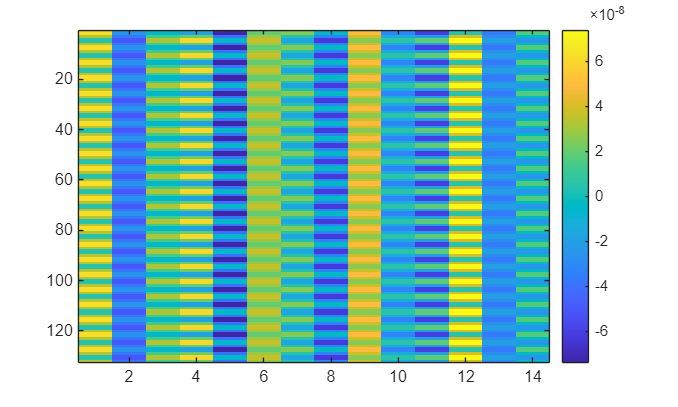


figure
imagesc(real(Hest_DD_TF_amp2));
colorbar

## Hybrid (Practical)

#### Hybrid OMP + Least Squares Refinement (Detailed Implementation)

function [x, support, history] = Hybrid_OMP_LS(A, y, K_sparse, options)
    % Hybrid approach: OMP for support detection + LS for debiasing
    %
    % This combines:
    %   1. OMP to find sparse support (which elements are non-zero)
    %   2. Least Squares refinement on the support for accurate values
    %
    % Inputs:
    %   A         - [M x N] complex sensing matrix
    %   y         - [M x 1] complex measurements
    %   K_sparse  - expected sparsity level
    %   options   - (optional) struct with fields:
    %               .threshold_factor: relative threshold (default: 0.01)
    %               .ls_refinement: enable LS refinement (default: true)
    %               .verbose: display progress (default: true)
    %               .max_support: maximum support size (default: K_sparse*2)
    %
    % Outputs:
    %   x         - [N x 1] estimated sparse signal
    %   support   - indices of non-zero elements
    %   history   - struct with algorithm information
    
    % Parse options
    if nargin < 4
        options = struct();
    end
    threshold_factor = getfield_default(options, 'threshold_factor', 0.01);
    ls_refinement = getfield_default(options, 'ls_refinement', true);
    verbose = getfield_default(options, 'verbose', true);
    max_support = getfield_default(options, 'max_support', K_sparse * 2);
    
    [M, N] = size(A);
    
    if verbose
        fprintf('=== Hybrid OMP + LS Refinement ===\n');
        fprintf('Problem size: M=%d, N=%d, K_sparse=%d\n', M, N, K_sparse);
    end
    
    %% Step 1: Run OMP to find initial support
    if verbose
        fprintf('\nStep 1: Running OMP for support detection...\n');
    end
    
    [x_omp, support_omp] = OMP_complex(A, y, K_sparse);
    
    if verbose
        fprintf('OMP found %d non-zero elements\n', length(support_omp));
        fprintf('OMP residual: %.2e\n', norm(y - A * x_omp));
    end
    
    %% Step 2: Refine support using threshold
    if verbose
        fprintf('\nStep 2: Refining support with threshold...\n');
    end
    
    % Compute adaptive threshold
    max_val = max(abs(x_omp));
    threshold = threshold_factor * max_val;
    
    % Find elements above threshold
    support = find(abs(x_omp) > threshold);
    
    % Limit support size
    if length(support) > max_support
        [~, idx] = sort(abs(x_omp(support)), 'descend');
        support = support(idx(1:max_support));
    end
    
    if verbose
        fprintf('Threshold: %.2e (%.1f%% of max)\n', threshold, threshold_factor*100);
        fprintf('Refined support size: %d\n', length(support));
    end
    
    %% Step 3: Least Squares refinement on support
    x = zeros(N, 1);
    
    if ls_refinement && ~isempty(support)
        if verbose
            fprintf('\nStep 3: LS refinement on support...\n');
        end
        
        % Check if problem is well-posed
        if length(support) <= M
            A_support = A(:, support);
            
            % Solve LS problem: min ||y - A_support * x_support||^2
            x_support = A_support \ y;
            
            % Assign to full vector
            x(support) = x_support;
            
            residual_refined = norm(y - A * x);
            
            if verbose
                fprintf('LS refinement complete\n');
                fprintf('Refined residual: %.2e\n', residual_refined);
                fprintf('Improvement: %.2f dB\n', ...
                    10*log10(norm(y - A*x_omp)^2 / residual_refined^2));
            end
        else
            warning('Support size (%d) > measurements (%d), skipping LS', ...
                length(support), M);
            x = x_omp;
        end
    else
        x = x_omp;
    end
    
    %% Store history
    history.support_omp = support_omp;
    history.support_refined = support;
    history.threshold = threshold;
    history.x_omp = x_omp;
    history.residual_omp = norm(y - A * x_omp);
    history.residual_final = norm(y - A * x);
end

[h_est_hybrid, support, history] = Hybrid_OMP_LS(A_test, y, K_sparse);

=== Hybrid OMP + LS Refinement ===
Problem size: M=1848, N=1848, K_sparse=5

Step 1: Running OMP for support detection...
OMP found 1 non-zero elements
OMP residual: 1.55e-08

Step 2: Refining support with threshold...
Threshold: 9.59e-10 (1.0% of max)
Refined support size: 1

Step 3: LS refinement on support...
LS refinement complete
Refined residual: 1.55e-08
Improvement: 0.00 dB


Hest_DD_hybrid = reshape(h_est_hybrid, 132, 14);
Hest_DD_TF_hybrid = fft(ifft(Hest_DD_hybrid, [], 2), [], 1);
nmse_dd = norm(H_perfect_n_DD - Hest_DD_hybrid)^2 / norm(H_perfect_n_DD)^2

nmse_dd = 0.2038

error_nmse = norm(H_perfect_n - Hest_DD_TF_hybrid)^2 / norm(H_perfect_n)^2

error_nmse = 0.2038


figure
imagesc(real(Hest_DD_TF_hybrid));
colorbar

function [x, support, history] = Hybrid_OMP_LS_Enhanced(A, y, K_sparse, options)
    % Enhanced hybrid with multiple refinement strategies
    %
    % Additional features:
    %   - Iterative support refinement
    %   - Regularized LS (for ill-conditioned problems)
    %   - Support expansion (add correlated atoms)
    %   - Support pruning (remove weak atoms)
    
    % Parse options
    if nargin < 4
        options = struct();
    end
    threshold_factor = getfield_default(options, 'threshold_factor', 0.01);
    verbose = getfield_default(options, 'verbose', true);
    max_support = getfield_default(options, 'max_support', K_sparse * 3);
    iterative_refinement = getfield_default(options, 'iterative_refinement', true);
    support_expansion = getfield_default(options, 'support_expansion', true);
    regularization = getfield_default(options, 'regularization', 1e-8);
    
    [M, N] = size(A);
    
    if verbose
        fprintf('=== Enhanced Hybrid OMP + LS ===\n');
    end
    
    %% Step 1: Initial OMP
    if verbose
        fprintf('\nPhase 1: Initial OMP...\n');
    end
    [x_omp, support] = OMP_complex(A, y, K_sparse);
    
    %% Step 2: Support expansion (add highly correlated atoms)
    if support_expansion && length(support) < max_support
        if verbose
            fprintf('\nPhase 2: Support expansion...\n');
        end
        
        residual = y - A * x_omp;
        correlations = abs(A' * residual);
        
        % Find additional atoms
        [sorted_corr, sorted_idx] = sort(correlations, 'descend');
        
        % Add atoms with correlation > threshold
        corr_threshold = 0.1 * sorted_corr(1);
        candidates = sorted_idx(sorted_corr > corr_threshold);
        candidates = setdiff(candidates, support);
        
        n_add = min(length(candidates), K_sparse);
        support_expanded = [support; candidates(1:n_add)];
        
        if verbose
            fprintf('Added %d atoms to support\n', n_add);
        end
    else
        support_expanded = support;
    end
    
    %% Step 3: LS refinement on expanded support
    if verbose
        fprintf('\nPhase 3: LS refinement on expanded support...\n');
    end
    
    x = zeros(N, 1);
    
    if length(support_expanded) <= M
        A_support = A(:, support_expanded);
        
        % Regularized LS for numerical stability
        % x_support = (A_support' * A_support + reg*I) \ (A_support' * y)
        AHA = A_support' * A_support;
        AHy = A_support' * y;
        x_support = (AHA + regularization * eye(length(support_expanded))) \ AHy;
        
        x(support_expanded) = x_support;
    else
        warning('Support too large, using OMP result');
        x = x_omp;
        support_expanded = support;
    end
    
    %% Step 4: Support pruning (remove weak atoms)
    if verbose
        fprintf('\nPhase 4: Support pruning...\n');
    end
    
    threshold = threshold_factor * max(abs(x));
    support_pruned = find(abs(x) > threshold);
    
    if verbose
        fprintf('Pruned %d weak atoms\n', ...
            length(support_expanded) - length(support_pruned));
    end
    
    %% Step 5: Final LS on pruned support
    if iterative_refinement && ~isempty(support_pruned)
        if verbose
            fprintf('\nPhase 5: Final LS refinement...\n');
        end
        
        x_final = zeros(N, 1);
        A_final = A(:, support_pruned);
        x_final(support_pruned) = A_final \ y;
        
        % Check if refinement improved
        if norm(y - A*x_final) < norm(y - A*x)
            x = x_final;
            support = support_pruned;
            if verbose
                fprintf('✓ Refinement improved solution\n');
            end
        else
            support = support_pruned;
            if verbose
                fprintf('✓ Kept previous solution\n');
            end
        end
    else
        support = support_pruned;
    end
    
    %% Summary
    if verbose
        fprintf('\n=== Final Results ===\n');
        fprintf('Final support size: %d\n', length(support));
        fprintf('Final residual: %.2e\n', norm(y - A*x));
        fprintf('NMSE: %.2f dB\n', ...
            10*log10(norm(y - A*x)^2 / norm(y)^2));
    end
    
    %% Store history
    history.support_omp = find(abs(x_omp) > 1e-10);
    history.support_expanded = support_expanded;
    history.support_final = support;
    history.x_omp = x_omp;
    history.residual_omp = norm(y - A * x_omp);
    history.residual_final = norm(y - A * x);
    history.threshold = threshold;
end


%% Options for enhanced version
options = struct();
options.threshold_factor = 0.01;
options.verbose = true;
options.max_support = K_sparse * 3;
options.iterative_refinement = true;  % Multiple refinement iterations
options.support_expansion = true;     % Add correlated atoms
options.regularization = 1e-8;        % Regularized LS

[h_est_hybrid2, support, history] = Hybrid_OMP_LS_Enhanced(A_test, y, K_sparse);

=== Enhanced Hybrid OMP + LS ===

Phase 1: Initial OMP...

Phase 2: Support expansion...
Added 5 atoms to support

Phase 3: LS refinement on expanded support...

Phase 4: Support pruning...
Pruned 0 weak atoms

Phase 5: Final LS refinement...
✓ Refinement improved solution

=== Final Results ===
Final support size: 6
Final residual: 1.25e-08
NMSE: -7.58 dB


Hest_DD_hybrid2 = reshape(h_est_hybrid2, 132, 14);
Hest_DD_TF_hybrid2 = fft(ifft(Hest_DD_hybrid2, [], 2), [], 1);
nmse_dd = norm(H_perfect_n_DD - Hest_DD_hybrid2)^2 / norm(H_perfect_n_DD)^2

nmse_dd = 0.1634

error_nmse = norm(H_perfect_n - Hest_DD_TF_hybrid2)^2 / norm(H_perfect_n)^2

error_nmse = 0.1634

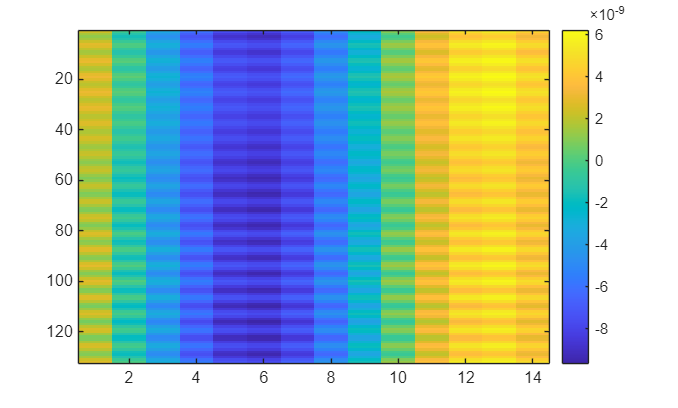


figure
imagesc(real(Hest_DD_TF_hybrid2));
colorbar

## CVX

% --- Inputs ---
% A: [M x N] convolution matrix (built from tx DD grid, M = #observations, N = #DD channel taps)
% y: [M x 1] observation vector (received DD grid, vectorized)
% N: number of DD taps (e.g., N = 132*14)

% --- Channel Estimation via Compressed Sensing (Basis Pursuit) ---

cvx_begin
    variable h_hat(N) complex          % Estimated DD channel coefficients
    minimize( norm(h_hat, 1) )         % Basis Pursuit (L1 minimization)
    subject to
        A * h_hat == y                 % Equality constraint (or A*h_hat ≈ y if noise)
cvx_end

% --- Reshape estimated channel back to DD grid (e.g. [132 x 14]) ---
H_DD_est = reshape(h_hat, 132, 14);

% --- Display (optional) ---
figure;
imagesc(abs(H_DD_est)); colorbar;
title('Estimated Sparse DD Channel (via CS)');

disp('Finished Compressed Sensing Recovery for DD channel.');